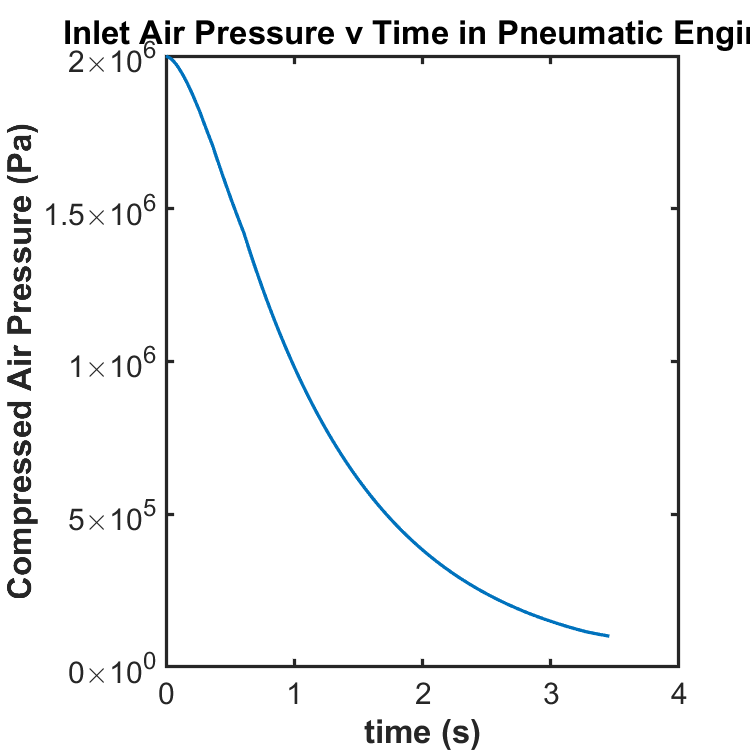

% compressed air engine project.

% this code will give you the plot of a compressed air engine's spinning speed
% against time. it is an important performance characteristic. 

% this model is a good simulation of a real pneumatic engine in a way that if your
% initial rotation speed is not high enough, you will not be able to initiate 
% the engine, just like what you will expect in the physical world if you
% don't hit the blade with enough force. 

% another interesting point to notice is when the compressed air is only at
% a slightly higher pressure than the atmospheric pressure, say 1.4 atm,
% the spinning will still stop just like what happens in reality.

% the general process for making the plot is as follows:

% 1. the total rounds the propeller will spin can be calculated by finding how much the
% compressed air pressure will decrease with each round (expressed as a fraction of the
% original pressure).

% 2. for each round of the spinning, the compressed air pressure is known, so
% the driving force and driving torque can be calculated for each round. 
% 
% 3. then based on newton's laws, rotational speed will be calculated with a timestep of
% 0.001 s for duration of less than 0.05 of the time each round takes. 

% 4. the calculated rotational speed is then plotted against time.

% NOTES
% you can simulate more compressed air by increasing the compressed air pressure
% simulate a harder initial hit of the blade by increasing the omega(1)
% simulate a larger turbine by increasing the moment of inertia of the rotor

clc; clear; close all;


% parameters
connecting_rod_length=30/1000; % 30mm
height_of_piston=12/1000; % connecting point to the rod is in the middle
crank_shaft_r=6/1000;
piston_r=10/1000;
piston_cross_area=pi*piston_r^2;
volume_of_inlet_air=piston_cross_area*height_of_piston;
volume_of_exterior_container=1/1000; % 1L container 
atmospheric_pressure=1*10^5;
moment_of_inertia=20*10^(-5); % rotational inertia of the whole rotor 
% (consider a 3 blades 50mmx20mmx4mm polystyrene rotor plus 20% extra inertia from other component)

Cp=0.03; % power coefficient of the propeller
k=Cp*0.5*1.2*pi*0.05^5; % propeller torque coefficient 
% 1.2 is the air density. 0.05 is the radius of the blade
Q=@(omega) k*omega^2; % propeller's impeding torque
friction_anti_torque=0.05; % anti-torque due to friction: 0.05 N*m

% the volume of inlet air is a constant. the pressure of it equals 
% to the compressed air. take the inlet and outlet process of air as instantaneous

n=20; % pressure in atm
initial_compressed_air_pressure=n*10^5; % n atomspheric pressure
pressure(1)=initial_compressed_air_pressure;
work_done=0;
omega(1)=60; % initial angular speed (you need to give it a push to initiate the spinning)

% calculate number of rounds
rounds=log(atmospheric_pressure/initial_compressed_air_pressure)/log(volume_of_exterior_container...
        /(volume_of_exterior_container+volume_of_inlet_air)); 
% code above calculates how many rotations the engine makes before it drops to atmospheric pressure
% (and therefore stops rotating)
% the reason it can be calculated this way is that the pressure will drop by a certain fraction after each round.

% calculate total work done compressing air into container
work=n*1.29/29*8.31*298*log(n); % work done to compress nL air into the 1L container assuming constant T(298K)

% calculating pressure after each rotation 
t(1)=0;
for i=1:2*rounds 
    if pressure(i)>1.01*10^5
        pressure(i+1)=pressure(i)*volume_of_exterior_container...
            /(volume_of_exterior_container+volume_of_inlet_air);
    else
        pressure(i+1)=pressure(i);
    end
    
    force(i)=(pressure(i)-atmospheric_pressure)*piston_cross_area;
    
    inner_dt=0.001;
    inner_time=0:inner_dt:0.6;
    % since each rotation will take less than 0.05s, duration of 0.05s is sufficient.
    past_radian(1)=0;
    w_inner=omega(i);
    work_done_inner=0;
    
    % below is the calculation for each rotation. w is the spinning speed which
    % will give the spinning speed of next rotation--omega(i+1)
    for j=1:length(inner_time)
        if w_inner(j)<0
            break
        elseif past_radian(j)<=pi
            w_inner(j+1)=w_inner(j)+(force(i)*crank_shaft_r...
                *sin(past_radian(j))*inner_dt-Q(w_inner(j))*inner_dt-friction_anti_torque*inner_dt)/moment_of_inertia;
            work_done_inner=work_done_inner+force(i)*crank_shaft_r*sin(past_radian(j))*w_inner(j+1)*inner_dt;
            % when radian is less than pi, the force from the compressed
            % air will cause a driving torque while the drag of air will
            % cause a anti-torque proportional to the square of the
            % spinning speed. also the friction impeding torque is taken
            % into consideration
        elseif past_radian(j)<2*pi
            w_inner(j+1)=w_inner(j)-(Q(w_inner(j))*inner_dt+friction_anti_torque*inner_dt)/moment_of_inertia;
            % when the radian passes pi, the driving torque will be gone
            % and the angular speed will decrease due to the friction and
            % the air drag
        else
            w_inner(j+1)=w_inner(j);
        end
        
        if past_radian(j)<=2*pi && past_radian(j)>=0
            past_radian(j+1)=past_radian(j)+w_inner(j)*inner_dt;
        else
            % if the radian is already past 2pi, it should stop increasing
            % as this is only for one round
            past_radian(j+1)=past_radian(j);
        end
    end
    
    % calculate the time this round will take by finding the index at which
    % the radian stays at 2pi multiplied by dt
    time_this_round_takes=find(past_radian==max(past_radian),1)*inner_dt;
    
    omega(i+1)=w_inner(end);
    t(i+1)=t(i)+time_this_round_takes;
    work_done=work_done+work_done_inner(end);
end

total_time=t(i+1);
% max_spinning_speed=omega(find(omega==max(omega)));
% kinetic_energy=1/2*moment_of_inertia*max_spinning_speed^2;
efficiency=work_done/work; % efficiency of this compressed air engine.
% it is calculated by dividing the work done to the rotor by the
% total work needed to compress the air into that 1L container.

pressure_end_index=find(pressure<=101000,1); % find when the pressure drops to atomspheric pressure
plot(t(1:pressure_end_index),pressure(1:pressure_end_index))
xlabel('time (s)')
ylabel('Compressed Air Pressure (Pa)')
title("Inlet Air Pressure v Time in Pneumatic Engine")

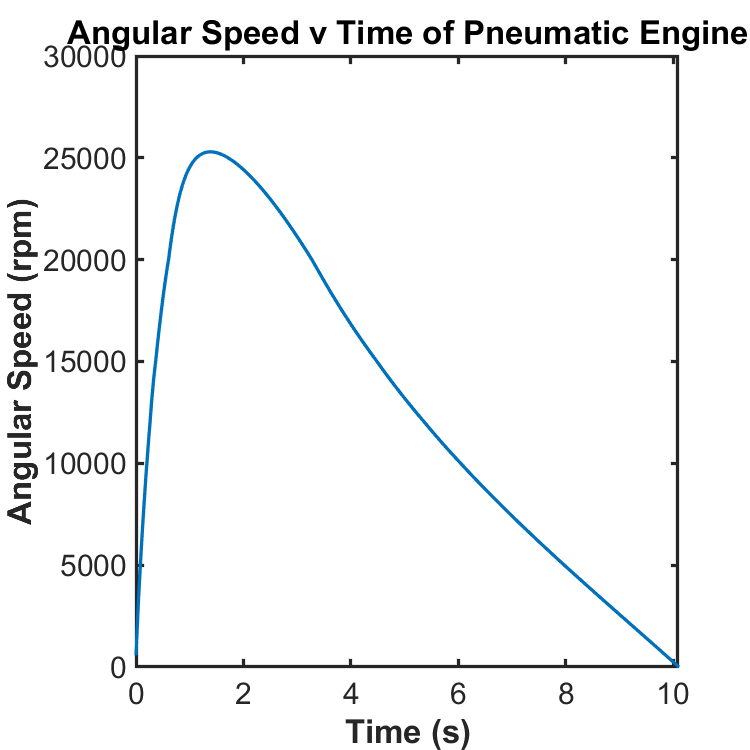


spinning_end_index=find(omega<=1,1); % find when the spin ends
plot(t(1:spinning_end_index),omega(1:spinning_end_index)/(2*pi)*60)
title("Angular Speed v Time of Pneumatic Engine")
xlabel('Time (s)')
ylabel('Angular Speed (rpm)')
ylim([0,30000])